clear all

Загрузка параметров

load curvefitting.mat

Описание данных с помощью функций (пытаемся использовать полиномы n-ой степени)

%   Строим модель, пытаемся описать все данные полиномом 5 степени poly5 
%   Все значения normalized by mean 1.061e+04 and std 2989


%   Разделить значения по расходам
%   значения начиная с 7500 (6 ая строка)

for i = 6:1:11

%   получение сил/моментов, соответствующих расходам
%   для каждой из сил строим и интерполируем(аппроксимируем) зависимость от частоты

%   Сохранение соответств. сил/моментов в 

Fr_cell{i-5}=Fr_comb{1,i};
Fx_cell{i-5}=Fx_comb{1,i};
Fy_cell{i-5}=Fy_comb{1,i};
Fz_cell{i-5}=Fz_comb{1,i};

Mr_cell{i-5}=Mr_comb{1,i};
Mx_cell{i-5}=Mx_comb{1,i};
My_cell{i-5}=My_comb{1,i};
Mz_cell{i-5}=Mz_comb{1,i};


end
%   объединяем, получаем ячейки, 
%   где строки - значения по x,y,z,r а столбцы - расходы
%   в самих ячейках вектор из 6 значений (точек) силы/момента для данного
%   расхода по возрастанию идут значения сил от скорости вращения от 7500 до 15000 

F_all=[Fx_cell; Fy_cell; Fz_cell; Fr_cell];
M_all = [Mx_cell; My_cell; Mz_cell; Mr_cell];

FplusM = [F_all; M_all];

Интерполяция визуально для каждого значения силы или момента

k=1;             %номер графика, их счётчик количества
for i = 1:8      %по всем силам и моментам
    for j = 1:6 %по расходам (по столбцам)
    % для всех строк (8)
    plotdata = FplusM{i,j};

    figure("Name","Силы/моменты от расхода")
    % % Сравнение полинома и интерполяции, кубическая работает лучше!
    %createFit_poly_vs_cubic(RPM_comb,plotdata);

k
    % Сохранить каждый результат в переменную с соответствующим именем
    % (расход и частота)
     [fitresult{i,j}, gof{i,j}] = createFit_cubic_interp(RPM_comb,plotdata);  
     
    % Сохранение графиков в переменную
    % plots{k}=plot(RPM_comb,plotdata,'b--o');
    k=k+1;
    end
end

Получение силы, на основании заданного расхода

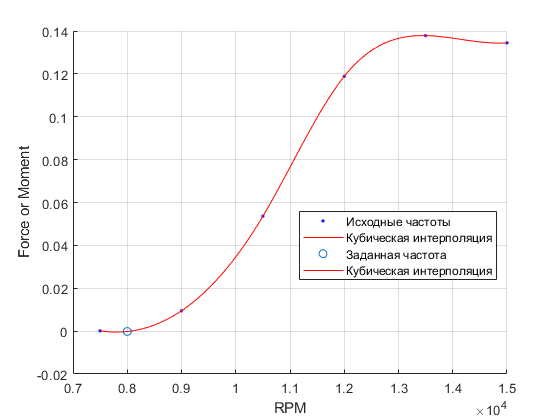

ForceOrMoment = -1.7011e-04

clf % очистка графиков в выводе

% Ввод частоты, расхода - получение значения силы
% задаем расход (ячека определяет проекцию вектора и расход,
% первый индекс m = 1 - Fx, m=2 - Fy, m=3 - Fz, m=4 - Fr, m=5 - Mx и т.д. m=8 - Mr аналогично,
% второй индекс n = 1 - расход 1 л/мин, n=6 - расход 6 л/мин

prompt = 'Выберите величину для поиска Fx, Fy, Fz, Fr, Mx, My, Mz, Mr: \n';
str = input(prompt, 's');
if isempty(str)
    str = 'Fx';
    m=1;
elseif str == "Fx"
    m=1;
elseif str == "Fy"
    m=2;
elseif str == "Fz"
    m=3;
elseif str == "Fr"
    m=4;
elseif str == "Mx"
    m=5
elseif str == "My"
    m=6;
elseif str == "Mz"
    m=7;
elseif str == "Mr"
    m=8;
end

prompt = 'Значение требуемого расхода от 1 до 6:\n';
n = input(prompt);
if isempty(n)
    n=1;
end
% m = 1; % выбор величины для поиска 1-4 = силы, 5-8 = моменты, см. выше
% n=1; % расход в л/мин по шкале от 1 до 6

prompt = 'Значение требуемой частоты вращения от 7500 до 15000 об/мин:\n';
RPMtofind = input(prompt);
if isempty(RPMtofind)
    RPMtofind=7500;
end
% Простое задание частоты вращения в об/мин в пределах от 7500 до 15000
% RPMtofind = 9500;

plotdata = FplusM{m,n}; % получаем вектор из ячейки из 3х мерного объекта

% Получаем значение силы на заданной частоте
ForceOrMoment = getForceOnRPMandFlow(RPM_comb,plotdata,RPMtofind)